## Set up

clc
clear
clf
rng(16);

Preprocessing

SmarketD = readtable("Data\SmarketShuffle.csv");
SmarketD.Direction = categorical(SmarketD.Direction);
summary(SmarketD);

Variables:

    Var1: 1250×1 double

        Values:

            Min            1  
            Median     625.5  
            Max         1250  

    Year: 1250×1 double

        Values:

            Min         2001  
            Median      2003  
            Max         2005  

    Lag4: 1250×1 double

        Values:

            Min        -4.922 
            Median     0.0385 
            Max         5.733 

    Lag3: 1250×1 double

        Values:

            Min        -4.922 
            Median     0.0385 
            Max         5.733 

    Lag1: 1250×1 double

        Values:

            Min        -4.922 
            Median      0.039 
            Max         5.733 

    Lag2: 1250×1 double

        Values:

            Min        -4.922 
            Median      0.039 
            Max         5.733 

    Lag5: 1250×1 double

        Values:

           

Smarket = normalize(SmarketD(:,3:end-1));
Smarket.Direction = SmarketD.Direction;

% corrplot(Smarket(:,1:end-1));

## LDA

train = (SmarketD.Year < 2005);
Smarket2005 = Smarket(~train,:);
Direction2005 = SmarketD.Direction(~train,:);
ldafit = fitcdiscr(Smarket(train, 1:end-2), Smarket(train, end));
Direction = SmarketD.Direction;
num_components = 2; % Number of components in the reduced space
[eigenvectors, eigenvalues] = eig(ldafit.BetweenSigma, ldafit.Sigma);
lambda = diag(eigenvalues);
[lambda, sorted_indices] = sort(lambda, 'descend');
projection_matrix = eigenvectors(:, sorted_indices(1:num_components));

Smarket_reduced = table2array(Smarket(:,1:end-2)) * projection_matrix;
Smarket2005_reduced = Smarket_reduced(~train,:);

num_neighbours = 5;
kNN_model_LDA = fitcknn(Smarket_reduced,Smarket.Direction, 'NumNeighbors', num_neighbours, 'Standardize', 1);

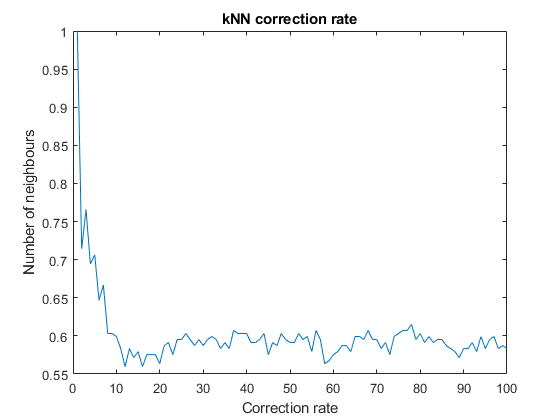

for i = 1:100
    kNN_model_LDA.NumNeighbors = i;
    y_pred = predict(kNN_model_LDA, Smarket2005_reduced);
    conf = confusionmat(Direction2005, y_pred);
    correction_rate(i) = sum(diag(conf))/sum(conf,"all");
end
[M, I] = max(correction_rate);
plot(1:100, correction_rate)
title('kNN correction rate');
xlabel('Correction rate');
ylabel('Number of neighbours');

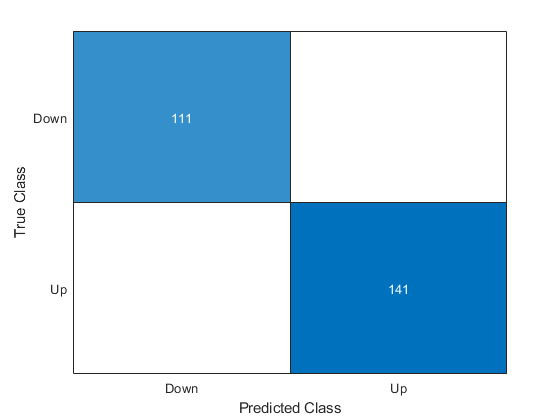


kNN_model_LDA.NumNeighbors = I;
y_pred = predict(kNN_model_LDA, Smarket2005_reduced);
C = confusionmat(Direction2005, y_pred);
confusionchart(Direction2005, y_pred);

disp('Confusion Matrix:');

Confusion Matrix:


disp(C);

   111     0
     0   141



correction_rate = sum(diag(C))/sum(C,"all");

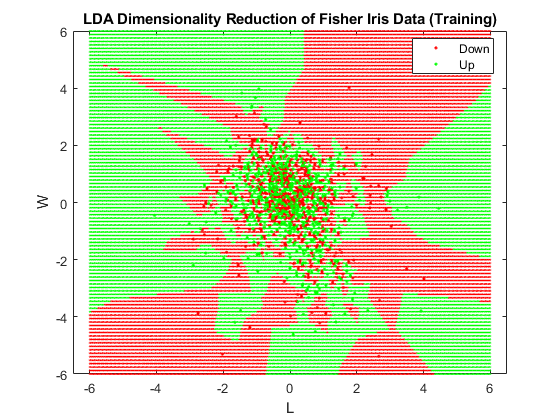

gscatter(Smarket_reduced(:, 1), Smarket_reduced(:, 2), Smarket.Direction, 'rg');
title('LDA Dimensionality Reduction of Fisher Iris Data (Training)');
xlabel('LDA Component 1');
ylabel('LDA Component 2');

[L, W] = meshgrid(linspace(-6, 6, 500), linspace(-6,6,100)); ...
L = L(:);
W = W(:);
pred = kNN_model_LDA.predict([L W]);
hold on;
h = gscatter(L, W, pred, 'rg', '.', 1, 'off'); set(h, 'LineWidth', 2, 'MarkerSize', 2)
legend('Down', 'Up', '', '');
hold off; 



% kNN_reduced = fitcdiscr(Smarket_reduced(train, :), Direction(train));
% 
% gscatter(Smarket_reduced(train, 1), Smarket_reduced(train, 2), Direction(train), 'rb');
% title('LDA Dimensionality Reduction of Smarket (Training)');
% xlabel('LDA Component 1');
% ylabel('LDA Component 2');
% legend('Up', 'Down', 'Location', 'best');
% 
% % [L, W] = meshgrid(linspace(-5, 5, 500), linspace(-5,5,100)); ...
% % L = L(:);
% % W = W(:);
% % pred = lda_reduced.predict([L W]);
% % hold on;
% % h = gscatter(L, W, pred, 'rb', '.', 1, 'off'); set(h, 'LineWidth', 2, 'MarkerSize', 2)
% % hold off; 
% 
% y_pred = predict(lda_reduced, Smarket2005_reduced);
% C = confusionmat(Direction2005, y_pred);
% disp('Confusion Matrix:');
% disp(C);

#### Prior probabilities

array2table(ldafit.Prior, 'VariableNames', cellstr(ldafit.ClassNames))

ans = 1×2 table
     Down        Up   
    _______    _______

    0.49198    0.50802


Group means

% array2table(ldafit.Mu, 'VariableNames',cellstr(ldafit.ClassNames))

Predictions

[ldaPredClass, ldaPredPosterior] = predict(kNN_model_LDA,Smarket2005_reduced);
confusionchart(ldaPredClass, Direction2005)

mean(ldaPredClass == Direction2005)

ans = 1

50% threshold

sum(ldaPredPosterior(:,1) >= 0.5)

ans = 111

sum(ldaPredPosterior(:,1) < 0.5)

ans = 141

ldaPredPosterior(1:20,1).'

ans =      1     1     1     0     1     0     1     0     1     0     0     1     1     1     1     0     0     0     1     0


ldaPredClass(1:20,1).'

ans = 1×20 categorical array
     Down      Down      Down      Up      Down      Up      Down      Up      Down      Up      Up      Down      Down      Down      Down      Up      Up      Up      Down      Up 



% 90 %
sum(ldaPredPosterior(:,1) >= 0.9)

ans = 111